# Proyecto Final Modelado - Sistema Cefalorraquídeo

## Datos del alumno

Alumnos: 

**Felix Gastelum Jesus Efren 20210781**

**Miriam Reyes Galvan 21212174**

**Brenda Mancilla Chavez 21212745**

Correo Institucional: **Jesus.felix201@tectijuana.edu.mx, L21212174@tectijuana.edu.mx, L21212745@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Carrera: **Ingeniería Biomédica**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos generales de la simulación

clc; clear all; close all;

tend = '10';
file = 'SistemaProyecto';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode45';

## Respuesta 

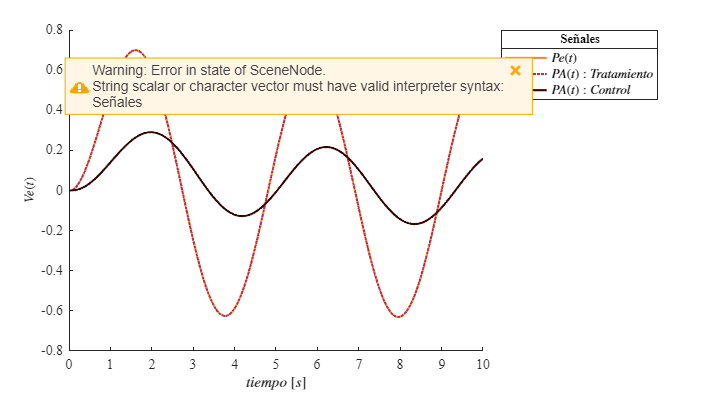

S= sim(file,parameters);
plotSignal(S.t,S.Pay,S.Paz,S.Pab)

## Función:

function plotSignal(t,Pay,Paz,Pab)
set(figure(), 'color', 'w')
set(gcf, 'units', 'centimeters', 'position',[1,5,18,10])
set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
hold on; grid off

plot(t, Pay, 'LineWidth',1.5, 'Color',[1,0.5,0.2])
plot(t, Paz, ':','LineWidth', 1.5 ,'Color',[0.7,0.2,0.3])
plot(t, Pab, 'LineWidth',1.5, 'Color',[0.2,0.02,0.02])

L = legend('$Pe(t)$','$PA(t): Tratamiento$','$PA(t): Control$','$PA(t): Caso$');
set(L,'Interpreter','Latex', 'FontSize', 9, 'Location','NorthEastOutside')
title(L,'Señales')

xlabel('$tiempo$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$Ve(t)$','Interpreter','Latex','FontSize',9)
 
xlim([0,10]); xticks (0:1:10)
ylim([-0.8,0.8]); yticks(-1:0.2:1)
name = 'PROYECTO.pdf';
exportgraphics(gcf,name,'ContentType','vector')
end
